clear
FN={};
FN(100)={[]};


Missing_Person={};
Missing_Person(100)={[]};
Missing_Person1={};
Missing_Person1(100)={[]};
Missing_Person2={};
Missing_Person2(100)={[]};

% CT = table(FN',SST',LST',SSO',LSO',vest',sling',shorts',trousers',skirt',SSD',LSD',vestDress',slingDress',...
%     'VariableNames',{'imageFilename' 'SST' 'LST' 'SSO' 'LSO' 'vest' 'sling' 'shorts' 'trousers' 'skirt' 'SSD' 'LSD' 'vestDress' 'slingDress'})

CT = table(FN',Missing_Person','VariableNames',{'imageFilename' 'Missing Person'})

CT = 100×4 table
    imageFilename    Missing Person    Missing Person1    Missing Person2
    _____________    ______________    _______________    _______________

    {0×0 double}      {0×0 double}      {0×0 double}       {0×0 double}  
    {0×0 double}      {0×0 double}      {0×0 double}       {0×0 double}  
    {0×0 double}      {0×0 double}      {0×0 double}       {0×0 double}  
    {0×0 double}      {0×0 double}      {0×0 double}       {0×0 double}  
    {0×0 double}      {0×0 double}      {0×0 double}       {0×0 double}  
    {0×0 double}      {0×0 double}      {0×0 double}       {0×0 double}  
    {0×0 double}      {0×0 double}      {0×0 double}       {0×0 double}  
    {0×0 double}      {0×0 double}      {0×0 double}       {0×0 double}  
    {0×0 double}      {0×0 double}      {0×0 double}       {0×0 double}  
    {0×0 double}      {0×0 double}      {0×0 double}       {0×0 double}  
    {0×0 double}      {0×0 double}      {0×0 double}       {0×0 double}  
    {0×0 double}    

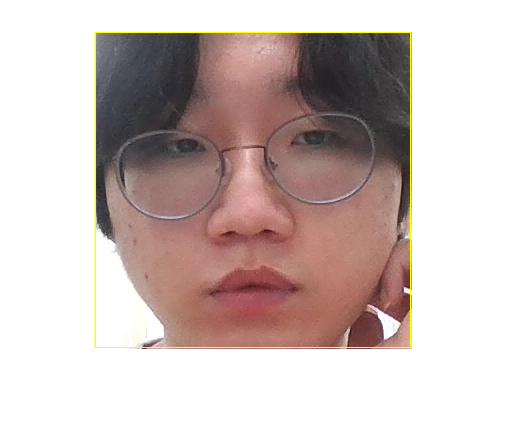

cam=webcam;
faceDetector=vision.CascadeObjectDetector;
c=100;
temp=0;
while true
    video_frame=cam.snapshot;
    bboxes =step(faceDetector,video_frame);
    if(sum(sum(bboxes))~=0)
    if(temp>=c)
        break;
    else
    filename=strcat(num2str(temp),'.jpg');
    imwrite(video_frame,filename);
% Writing filename into the table
    fname=['making_test\',filename];
    CT{temp+1,1}={fname};
% Writing bboxes into the table
    CT{temp+1,2}={bboxes(1,:)};
    temp=temp+1;
    video_frame = insertObjectAnnotation(video_frame, 'rectangle', bboxes(1,:), 'Face');
    video_face=imcrop(video_frame,bboxes(1,:));
%     filename2=strcat(num2str(temp),'_crop.jpg');
%     imwrite(video_face,filename2);
    imshow(video_face);
    drawnow;
    end
    else
        imshow(video_frame);
        drawnow;
    end
end

save('FaceTable',"CT")